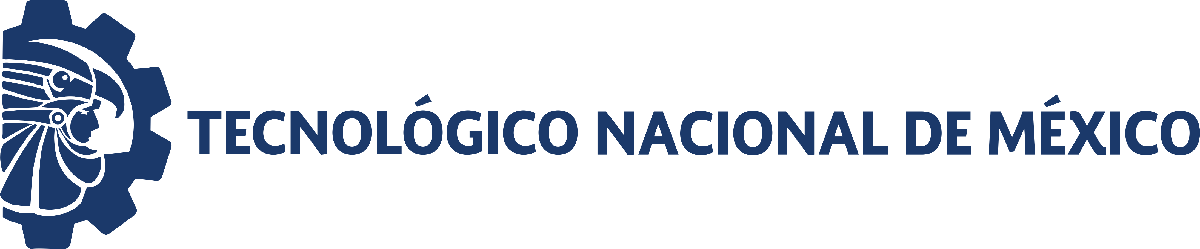                                 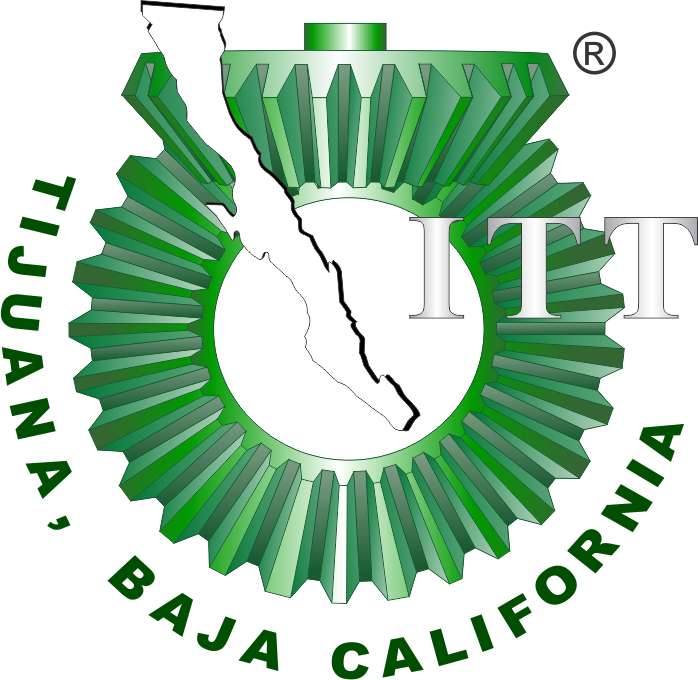

# Práctica: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

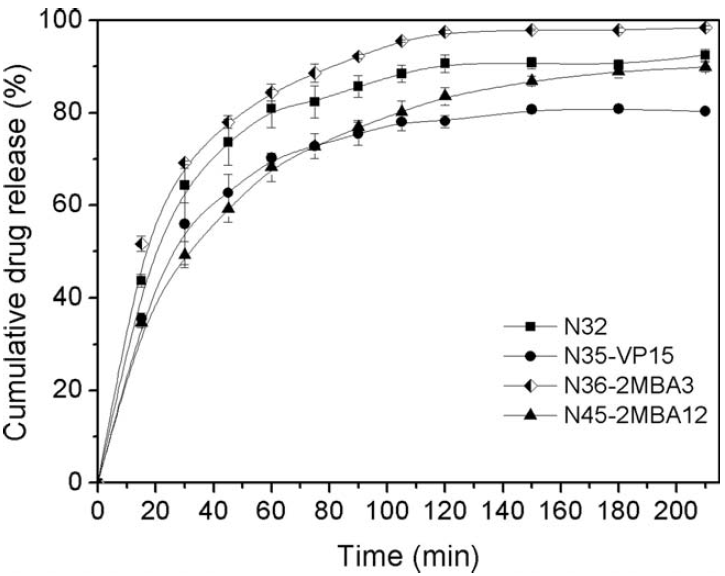

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $


$$Eureqa: x(t) = \rho1 + t - \rho2*t^2$$



$$EDO eureqa: 2.28 - \rho1 x$$


## Datos experimentales

clc; clear; close all; warning('off','all')
[t,x1, x2, x3, x4] = getdata ('data.csv');
T = array2table([t,x1,x2,x3,x4],'VariableNames',{'t[min]','N45','N32','N35','N36'}); disp(T)

    t[min]      N45         N32        N35         N36   
    ______    ________    _______    ________    ________

       0      -0.26525    -0.5305    -0.17683    -0.26525
      15        34.218     43.501      35.544      51.636
      31        49.602     64.191      56.057      68.966
      45        59.416     74.005      62.423      78.338
      60         68.17     81.167      70.203      84.527
      75        72.944     82.759      73.033      88.948
      90        77.454     85.942      75.508      92.573
     105        80.371     88.594      78.338      95.756
     120         83.82     90.981      78.338      97.613
     150        87.268     90.981      81.167      98.143
     180        88.859     90.981      81.167      98.497
     211        89.655     92.838      80.106      98.408



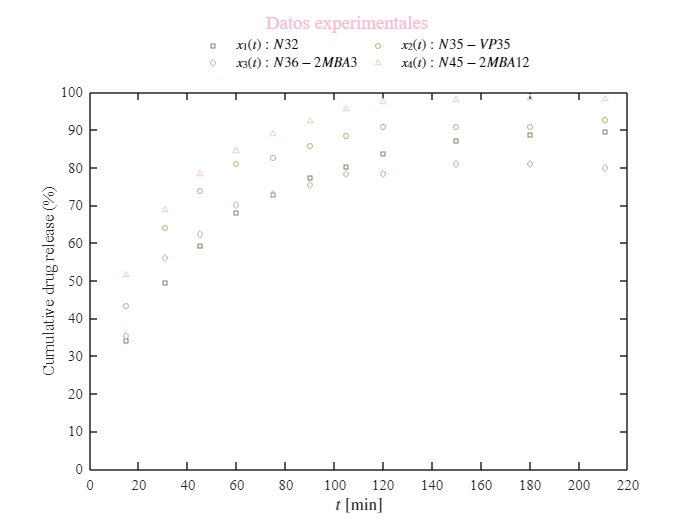

plotsys (t,x1, x2, x3, x4); sgtitle ('Datos experimentales','Color', '#F8BBD0', 'FontName', 'Times New Roman'); 
exportgraphics(gcf, 'data_raw.pdf', 'ContentType', 'vector')

### Regresión no lineal, biostadísticos y experimentación in silico

labels = {'x1(t): N45-2MBA12', 'x2(t): N32', 'x3(t): N35-VP15', 'x4(t): 2MBA3'};
xo = [x1, x2, x3,x4];s=size(xo);

### Funcion de Pepas

n0= 0.1; k0 = 0.1;xp = zeros (s(1), s(2));
for i = 1:4
   disp (['Resultados para el hidrogel: ', string (labels(i))]);
   mdl = peppas (t, xo(:,i), [n0;k0]);
   xp(:,i) = mdl.Fitted; disp ('');
end

    "Resultados para el hidrogel: "    ""    "x1(t): N45-2MBA12"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE         MoE              CI95             PValue  
    __________    ________    ________    ________    __________________    __________

      {'k'}          17.7       2.2989      5.1222     12.577     22.822    1.6445e-05
      {'n'}       0.31654     0.027659    0.061629    0.25491    0.37817    4.5577e-07

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.97769
Suma residual de cuadrados:177.4724
Criterio de informacion de Akaike ajustado:71.7148


    "Resultados para el hidrogel: "    ""    "x2(t): N32"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE         MoE              CI95             PValue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        30.262       4.3141      9.6125      20.65     39.875    3.6502e-05
      {'n'}       0.22207     0.030828    0.068688    0.15338    0.29076    2.9139e-05

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.96299
Suma residual de cuadrados:306.5789
Criterio de informacion de Akaike ajustado:78.2747


    "Resultados para el hidrogel: "    ""    "x3(t): N35-VP15"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE         MoE              CI95             PValue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        24.655        3.887      8.6607     15.995     33.316    8.4268e-05
      {'n'}       0.23712     0.034003    0.075764    0.16135    0.31288    3.8373e-05

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.95719
Suma residual de cuadrados:278.4926
Criterio de informacion de Akaike ajustado:77.1217


    "Resultados para el hidrogel: "    ""    "x4(t): 2MBA3"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE         MoE              CI95             PValue  
    __________    ________    ________    ________    __________________    __________

      {'k'}         34.12       3.9111      8.7145     25.405     42.834    5.4714e-06
      {'n'}       0.21158     0.024834    0.055334    0.15625    0.26692    6.7554e-06

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.97466
Suma residual de cuadrados:233.0363
Criterio de informacion de Akaike ajustado:74.9833


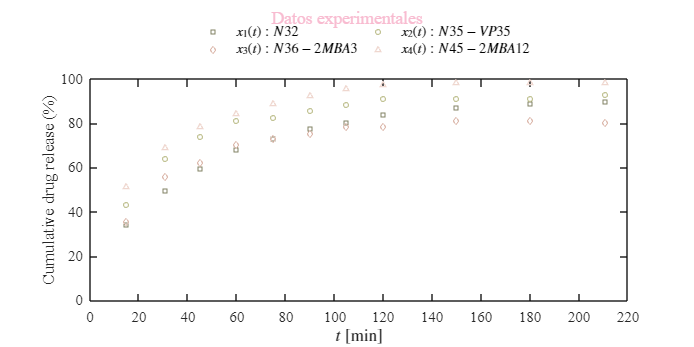

plotpepp (t,x1, x2, x3, x4,xp); sgtitle ('Peppas','Color', '#F8BBD0', 'FontName', 'Times New Roman'); 

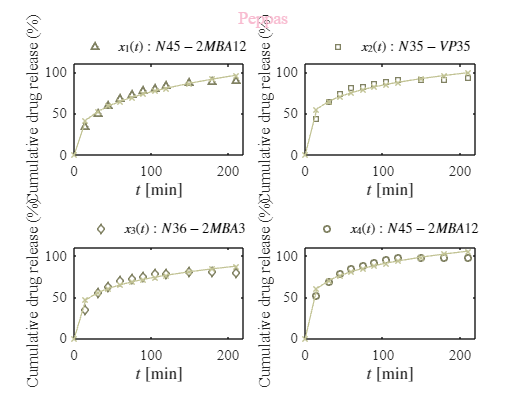

exportgraphics(gcf, 'peppas.pdf', 'ContentType', 'vector')

### Función de farmacocinética

beta0 = 100; k0=0.01; xfc = zeros(s(1), s(2)); 
for i = 1:4
   disp (['Resultados para el hidrogel: ', string (labels(i))]);
   mdl = farmacocinetica (t, xo(:,i), [beta0;k0]);
   xfc(:,i) = mdl.Fitted; disp ('');
end

    "Resultados para el hidrogel: "    ""    "x1(t): N45-2MBA12"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE           MoE               CI95              PValue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       88.045       1.3594       3.0288      85.016      91.074    1.8736e-14
     {'k'   }     0.025773    0.0013952    0.0031088    0.022664    0.028881    4.6606e-09

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.99246
Suma residual de cuadrados:60.0224
Criterio de informacion de Akaike ajustado:58.7056


    "Resultados para el hidrogel: "    ""    "x2(t): N32"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE          MoE               CI95              PValue  
    __________    ________    ________    _________    ____________________    __________

     {'beta'}        90.43     0.78527       1.7497       88.68       92.18    5.9797e-17
     {'k'   }     0.039506    0.001595    0.0035539    0.035952     0.04306    2.6297e-10

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.99598
Suma residual de cuadrados:33.2891
Criterio de informacion de Akaike ajustado:51.6317


    "Resultados para el hidrogel: "    ""    "x3(t): N35-VP15"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE          MoE               CI95              PValue  
    __________    ________    _________    ________    ____________________    __________

     {'beta'}       79.818      0.65465      1.4586      78.359      81.277    3.3792e-17
     {'k'   }     0.036642    0.0013298    0.002963    0.033679    0.039605    9.1867e-11

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.99669
Suma residual de cuadrados:21.5072
Criterio de informacion de Akaike ajustado:46.3897


    "Resultados para el hidrogel: "    ""    "x4(t): 2MBA3"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE           MoE               CI95              PValue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}      96.557        1.3549        3.019      93.539      99.576     7.219e-15
     {'k'   }     0.04114     0.0027563    0.0061414    0.034999    0.047282    3.6668e-08

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.98882
Suma residual de cuadrados:102.8084
Criterio de informacion de Akaike ajustado:65.1634


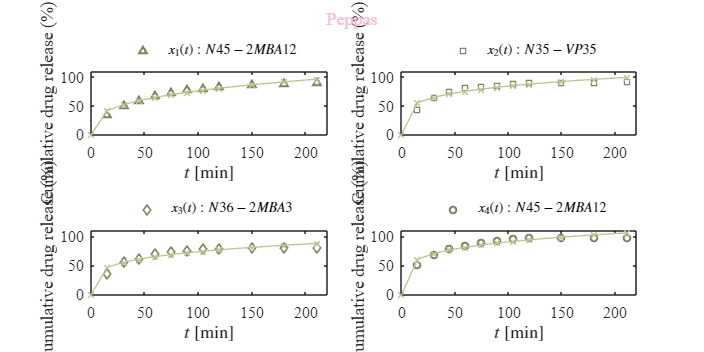

plotpepp (t,x1, x2, x3, x4,xp); sgtitle ('Farmacocinetica','Color', '#F8BBD0', 'FontName', 'Times New Roman'); 

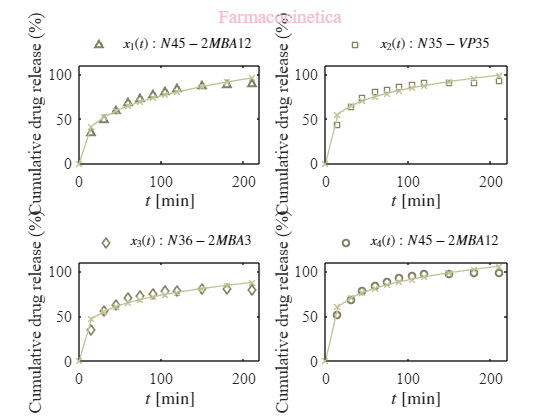

exportgraphics(gcf, 'farmocinetica.pdf', 'ContentType', 'vector')

### Función de primer orden


rho1_0 = 16.5673788017863; rho2_0=1; rho3_0 = 0.00333231533926082; xeu = zeros(s(1), s(2)); 
for i = 1:4
   disp (['Resultados para el hidrogel: ', string (labels(i))]);
   mdl = eureqa (t, xo(:,i), [rho1_0;rho2_0; rho3_0]);
   xeu(:,i) = mdl.Fitted; disp ('');
end

    "Resultados para el hidrogel: "    ""    "x1(t): N45-2MBA12"



Degrees of freedom:9
t-students value :2.2622
Alpha:0.05
 
    Parameters    Estimate         SE           MoE                CI95               PValue  
    __________    _________    __________    _________    ______________________    __________

     {'rho1'}        14.436        5.0747        11.48       2.9564       25.916      0.019254
     {'rho2'}       0.99822       0.11603      0.26247      0.73575       1.2607    1.2326e-05
     {'rho3'}     0.0031764    0.00053839    0.0012179    0.0019585    0.0043944    0.00022911

Amount of data: 12
Number of parameters: 3
R-cuadrada ordinaria:0.93958
Suma residual de cuadrados:480.7442
Criterio de informacion de Akaike ajustado:87.3397


    "Resultados para el hidrogel: "    ""    "x2(t): N32"



Degrees of freedom:9
t-students value :2.2622
Alpha:0.05
 
    Parameters    Estimate         SE           MoE                CI95               PValue  
    __________    _________    __________    _________    ______________________    __________

     {'rho1'}         21.69         7.849       17.756       3.9345       39.446      0.021988
     {'rho2'}         1.079       0.17946      0.40597      0.67304        1.485    0.00019942
     {'rho3'}     0.0037305    0.00083273    0.0018838    0.0018468    0.0056143     0.0015327

Amount of data: 12
Number of parameters: 3
R-cuadrada ordinaria:0.86117
Suma residual de cuadrados:1150.0737
Criterio de informacion de Akaike ajustado:97.8066


    "Resultados para el hidrogel: "    ""    "x3(t): N35-VP15"



Degrees of freedom:9
t-students value :2.2622
Alpha:0.05
 
    Parameters    Estimate         SE           MoE                CI95               PValue  
    __________    _________    __________    _________    ______________________    __________

     {'rho1'}        17.542        6.3408       14.344       3.1981       31.886      0.021878
     {'rho2'}       0.96766       0.14498      0.32796       0.6397       1.2956    9.1138e-05
     {'rho3'}     0.0033416    0.00067272    0.0015218    0.0018198    0.0048634    0.00077279

Amount of data: 12
Number of parameters: 3
R-cuadrada ordinaria:0.88462
Suma residual de cuadrados:750.5626
Criterio de informacion de Akaike ajustado:92.6855


    "Resultados para el hidrogel: "    ""    "x4(t): 2MBA3"



Degrees of freedom:9
t-students value :2.2622
Alpha:0.05
 
    Parameters    Estimate         SE           MoE                CI95               PValue  
    __________    _________    __________    _________    ______________________    __________

     {'rho1'}        24.586        8.3137       18.807       5.7795       43.393      0.016029
     {'rho2'}        1.1363       0.19008         0.43      0.70626       1.5663    0.00020813
     {'rho3'}     0.0039299    0.00088203    0.0019953    0.0019346    0.0059252     0.0015876

Amount of data: 12
Number of parameters: 3
R-cuadrada ordinaria:0.85967
Suma residual de cuadrados:1290.2782
Criterio de informacion de Akaike ajustado:99.187


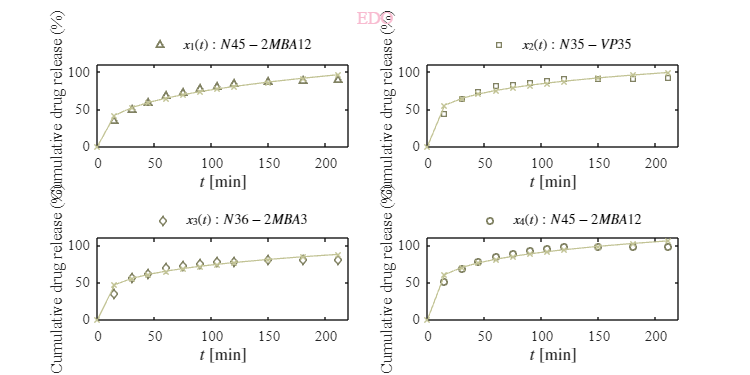

plotpepp (t,x1, x2, x3, x4,xp); sgtitle ('eureqa','Color', '#F8BBD0', 'FontName', 'Times New Roman'); 

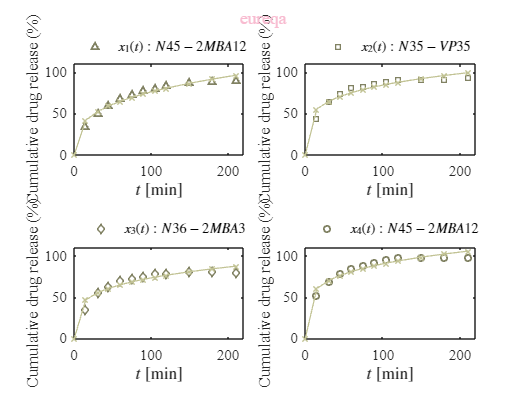

exportgraphics(gcf, 'eureqa.pdf', 'ContentType', 'vector')

### Función de farmacocinetica de primer orden

r1 = [2.29856104203723,3.186,2.671,3.501];  
r2 = [0.0259881781667291, 0.03491, 0.03323,0.03545];  

x0 = [x1, x2, x3, x4]; 
t = t(:); 
s = size(x0); 
xed = zeros(s(1), s(2));

Parameters = {'rho1'; 'rho2'};

for i = 1:4
    disp(['Resultados para el Hidrogel:', string(labels(i))]);
    [~, solV]  = ode89(@(t,x) eureqaODE(x, [r1(i), r2(i)]), t, x0(1,i));
    xed(:,i)   = solV;
    mdl = fitnlm(t, x0(:,i), ...
                 @(par, tq) modelODE(tq, x0(1,i), par), ...
                 [r1(i), r2(i)]);   
        biostats(mdl, Parameters)
end

    "Resultados para el Hidrogel:"    "x1(t): N45-2MBA12"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE           MoE               CI95              PValue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       2.2781      0.10038      0.22366      2.0544      2.5017    6.2165e-10
     {'rho2'}     0.025887    0.0014178    0.0031591    0.022728    0.029046    5.2199e-09

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.99223
Suma residual de cuadrados:61.7845
Criterio de informacion de Akaike ajustado:59.0528


    "Resultados para el Hidrogel:"    "x2(t): N32"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE           MoE               CI95              PValue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       3.5955      0.12944      0.28842      3.3071       3.884    8.4843e-11
     {'rho2'}     0.039777    0.0016268    0.0036248    0.036152    0.043402    2.9864e-10

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.99584
Suma residual de cuadrados:34.4392
Criterio de informacion de Akaike ajustado:52.0393


    "Resultados para el Hidrogel:"    "x3(t): N35-VP15"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE          MoE              CI95              PValue  
    __________    ________    _________    ________    ___________________    __________

     {'rho1'}       2.9319     0.093014     0.20725     2.7247      3.1392    2.4271e-11
     {'rho2'}     0.036739    0.0013415    0.002989    0.03375    0.039728    9.7553e-11

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.99664
Suma residual de cuadrados:21.8399
Criterio de informacion de Akaike ajustado:46.5738


    "Resultados para el Hidrogel:"    "x4(t): 2MBA3"



Degrees of freedom:10
t-students value :2.2281
Alpha:0.05
 
    Parameters    Estimate       SE           MoE               CI95              PValue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       3.9851      0.23768      0.52957      3.4555      4.5147    1.1939e-08
     {'rho2'}     0.041281    0.0027796    0.0061933    0.035087    0.047474    3.8474e-08

Amount of data: 12
Number of parameters: 2
R-cuadrada ordinaria:0.98867
Suma residual de cuadrados:104.2093
Criterio de informacion de Akaike ajustado:65.3258


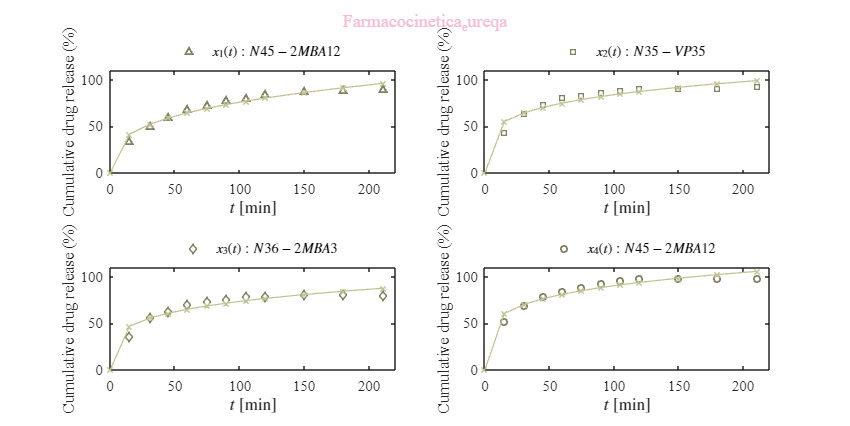

plotpepp (t,x1, x2, x3, x4,xp); sgtitle ('Farmacocinetica_eureqa','Color', '#F8BBD0', 'FontName', 'Times New Roman'); 

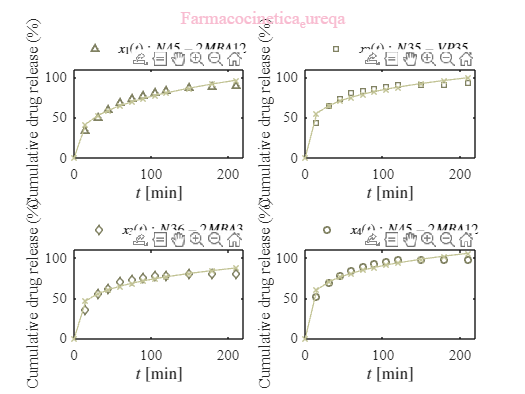

exportgraphics(gcf, 'Farmacocinetica_eureqa.pdf', 'ContentType', 'vector')

## Funciones

function plotsys (t,x1,x2,x3, x4)
palette = [129 130 99;
    194 195 149;
    221 186 174;
    239 215 207;
    220 212 193]/255;

	set(figure(), 'Color','w')
	FS = 12;

	set(gcf, 'units', 'Centimeters', 'Position', [1,1,20,15] )
    set(gca,'ColorOrder', palette)
	hold on; box on; grid off;
	plot(t,x1, 's', 'LineWidth', 1, 'MarkerSize',4)
    plot(t, x2, 'o', 'LineWidth', 1, 'MarkerSize',4)
    plot(t, x3, 'diamond', 'LineWidth', 1, 'MarkerSize',4)
    plot(t, x4, '^', 'LineWidth', 1, 'MarkerSize',4)
	xlabel('$t$ [min]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('Cumulative drug release (%)', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
    xlim ([0 220])
    ylim ([0, 100])
    L = legend ('$x_1(t): N32$', '$x_2(t): N35-VP35$', '$x_3(t): N36-2MBA3$','$x_4(t): N45-2MBA12$');...
    set (L,'Interpreter','Latex','Location', 'NorthOutside', 'Orientation', 'Horizontal',...
    'Box', 'Off', 'NumColumns',2)


    exportgraphics(gcf, 'data_raw.pdf', 'ContentType', 'vector')

end

function [t,x1,x2, x3, x4] = getdata(file)
     sys = readmatrix(file);
     t = round (sys(:,1));
     x1= sys(:,2);
     x2= sys(:,3);
     x3= sys(:,4);
     x4= sys(:,5);

end 


### Regresión: Función de Pepas 

    function mdl = peppas (to,xo,par)

    function x = model (par,t)
       k = par (1); n = par (2);
       x = k*t.^n;
    end

   mdl = fitnlm (to,xo, @model,par);
   Parameters = {'k'; 'n'};
   biostats (mdl, Parameters)
end 

function mdl = farmacocinetica (to,xo,par)

    function x1 = model (par,t)
       beta = par (1); k = par (2);
       x1 = beta*(1-exp(-k*t));
    end

   mdl = fitnlm (to,xo, @model,par);
   Parameters = {'beta'; 'k'};
   biostats (mdl, Parameters)
end 

function mdl = eureqa (to,xo,par)
    function x2 = model (par, t)
       rho1 = par (1); rho2 = par (2); rho3 = par (3);
       x2 = rho1 + rho2*t - rho3*t.^2; 
    end

   mdl = fitnlm (to,xo, @model,par);
   Parameters = {'rho1'; 'rho2' ;'rho3'};
   biostats (mdl, Parameters)
end 
 
function dxdt = eureqaODE(x1,par)
     r1   = par(1); r2   = par(2);
     dxdt = r1 - r2*x1;
end 
function xsim = modelODE(tq, x0_i, par)
    tq = tq(:);                          
    t_span = linspace(tq(1), tq(end), max(500, length(tq)*10))';
    [t_sol, sol] = ode89(@(t,x) eureqaODE(x, par), t_span, x0_i);
    xsim = interp1(t_sol, sol, tq, 'linear', 'extrap');
end

function biostats (mdl,Parameters)
            Estimate = table2array(mdl.Coefficients(:,1));
            SE = table2array(mdl.Coefficients(:,2));
            PValue = table2array(mdl.Coefficients(:,4));
            alpha = 0.05;
            CI95 = coefCI(mdl,alpha);
            dof = mdl.DFE;
            tval = tinv(1-alpha/2,dof);
            MoE = SE*tval;

            Results = table (Parameters, Estimate, SE, MoE,CI95,PValue);
            disp(['Degrees of freedom:', num2str(dof)])
            disp (['t-students value :', num2str(tval)])
            disp (['Alpha:', num2str(alpha)])
            disp (' '); disp (Results)
            R2o = mdl.Rsquared.Ordinary;
            SSE = mdl.SSE;
            AICc = mdl.ModelCriterion.AICc;
            fprintf('Amount of data: %d\n', mdl.NumObservations);
            fprintf('Number of parameters: %d\n', mdl.NumCoefficients);
            fprintf(['R-cuadrada ordinaria:', num2str(R2o), '\n']); ...
            fprintf (['Suma residual de cuadrados:', num2str(SSE),'\n']);...
            fprintf (['Criterio de informacion de Akaike ajustado:', num2str(AICc), '\n']);
end

function plotpepp (t, x1,x2,x3, x4,xp)

    palette = [129 130 99;
    194 195 149;
    221 186 174;
    239 215 207;
    220 212 193]/255;

    FS = 12;

    set(gcf, 'units', 'Centimeters', 'Position', [1,1,24,12] )
    set(figure(), 'Color','w')
    
	subplot (2,2,1); hold on; box on; grid off; 
    xlim ([0 220]);ylim ([0, 110])
    set(gca,'ColorOrder', palette)
	hold on; box on; grid off;
	plot(t,x1,'^','MarkerSize',5,'LineWidth',1.5)
    plot(t,xp(:,1),'-x','LineWidth',1)
	xlabel('$t$ [min]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('Cumulative drug release (%)', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
    L = legend ('$x_1(t): N45-2MBA12$');...
    set (L,'Interpreter','Latex','Location', 'NorthOutside', 'Orientation', 'Horizontal',...
    'Box', 'Off')

    subplot (2,2,2); hold on; box on; grid off; 
    xlim ([0 220]);ylim ([0, 110])
    set(gca,'ColorOrder', palette)
	hold on; box on; grid off;
	plot(t,x2,'s','MarkerSize',5,'LineWidth',1.5)
    plot(t,xp(:,2),'-x','LineWidth',1)
	xlabel('$t$ [min]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('Cumulative drug release (%)', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
    L = legend ('$x_2(t): N35-VP35$');...
    set (L,'Interpreter','Latex','Location', 'NorthOutside', 'Orientation', 'Horizontal',...
    'Box', 'Off')
    
    subplot (2,2,3); hold on; box on; grid off; 
    xlim ([0 220]);ylim ([0, 110])
    set(gca,'ColorOrder', palette)
	hold on; box on; grid off;
	plot(t,x3,'diamond','MarkerSize',5,'LineWidth',1.5)
    plot(t,xp(:,3),'-x','LineWidth',1)
	xlabel('$t$ [min]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('Cumulative drug release (%)', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
    L = legend ('$x_3(t): N36-2MBA3$');...
    set (L,'Interpreter','Latex','Location', 'NorthOutside', 'Orientation', 'Horizontal',...
    'Box', 'Off')
    
    subplot (2,2,4); hold on; box on; grid off; 
    xlim ([0 220]);ylim ([0, 110])
    set(gca,'ColorOrder', palette)
	hold on; box on; grid off;
	plot(t,x4,'o','MarkerSize',5,'LineWidth',1.5)
    plot(t,xp(:,4),'-x','LineWidth',1)
	xlabel('$t$ [min]',  'Interpreter','Latex', 'FontSize',FS)
    ylabel('Cumulative drug release (%)', 'Interpreter','Latex', 'FontSize', FS)
    set(gca,'FontName', 'Times New Roman', 'FontSize',FS)
    L = legend ('$x_4(t): N45-2MBA12$');...
    set (L,'Interpreter','Latex','Location', 'NorthOutside', 'Orientation', 'Horizontal',...
    'Box', 'Off')

end